**Perceive Medtronic-CU Anschutz Collaboration **

Part 1: Import all necessary values and create global variables. 

%% loads in json file
%loads in file
cd('C:\Users\sydne\Documents\github\perceive\patientData\Patient1_0524')
jsonFiles = 'Report_Json_Session_Report_20210524T101039.json';
js = jsondecode(fileread(jsonFiles));
%sets it back to the path where all the other functions are
cd('C:\Users\sydne\Documents\github\perceive')

%declares "global" variables AND determines if .json comes from
%single or double battery B)
channels = unique({js.LfpMontageTimeDomain.Channel}, 'stable');
leng = numel({js.LfpMontageTimeDomain.Channel});
startindex = 7; %MUST BE MANUALLY SET IN CLINIC
sides = {'LEFT', 'RIGHT'};
if any((contains(channels, sides{1}))) && any((contains(channels, sides{2})))
    doubleBattery = false;
    %json has both left and right data
    channelsLeft = channels(contains(channels, sides{1}));
    channelsRight = channels(contains(channels, sides{2}));
    channelSides = {channelsLeft, channelsRight}; 
    highestBetas = {' ', ' '};
else
    doubleBattery = true;
    %added this to help with titling figures 
    if contains(channels, sides{1})
        side = 'LEFT';
    else 
        side = 'RIGHT'; 
    end
end

Part 2: Create freq vs pwr plot for all 6 contacts. Also reports the max betas. 

    "The following information is for the"    "RIGHT"



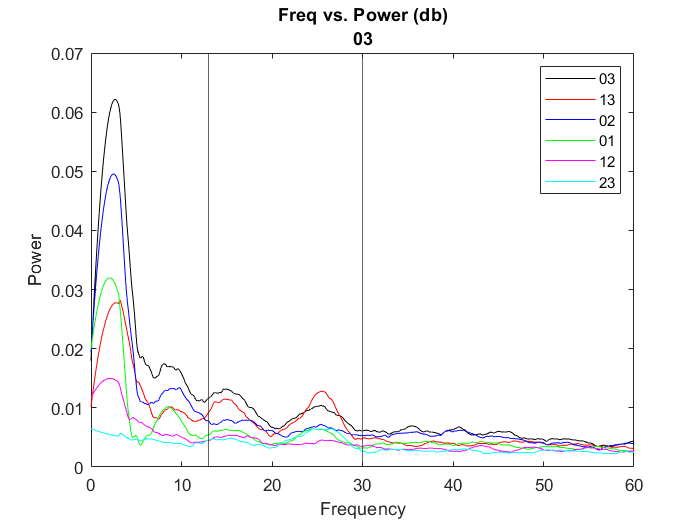

The highest beta comes from contact pair 03


%% run to get full graph
%{} gets the thing from the actual cell array
%() gets cell ARRAY!

close

if doubleBattery == false
    %this should be true if the json returns both left and right data,
    %single battery
    for  i = 1:2
        subplot(2, 1, i)
        channels2 = channels(contains(channels,sides{i}));
        colors = 'krbgmc';
        maxValues = zeros(length(channels2), 1);
        for c=1:length(channels2)
            maxValues(c) = tempAvgPlot(startindex, leng, js, channels2{c}, colors(c));
            hold on;
        end
        
        [M, I] = max(maxValues);
        highestBeta = channels2{I};
        highestBetas{i} = highestBeta;
        
        %add all the plot info
        xline(13);
        xline(30);
        
        %formats the channels to be suitable for the legend
        legendChan = cell(6);
        oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
        newchar = {''};
        oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
        newnum = {'0', '1', '2', '3'};
        for b = 1:length(channels2)
            legendChan{b} = replace(channels2{b}, oldchar, newchar);
            legendChan{b} = replace(legendChan{b}, oldnum, newnum);
        end
        
        legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
        title(["Freq vs. Power (db)", sides{i}, legendChan{I}])
        xlim([0 60])
        xlabel("Frequency")
        ylabel("Power")
        
        disp(['The highest beta comes from contact pair ', legendChan{I}])
        

    end
    
    
else
    %should be true if a double battery
    x = 0;
    %leng = numel({js.LfpMontageTimeDomain.Channel});
    %channels2 = channels(contains(channels,sides{i}));
    
    disp(["The following information is for the", convertCharsToStrings(side)]); 
    
    colors = 'krbgmc';
    maxValues = zeros(length(channels), 1);
    for c=1:length(channels)
        maxValues(c) = tempAvgPlot(startindex, leng, js, channels{c}, colors(c));
        hold on;
    end
    
    [M, I] = max(maxValues);
    highestBeta = channels{I};
    
    %add all the plot info
    
    xline(13);
    xline(30);
    
    %these are the order presented in channels
    
    legendChan = cell(6);
    oldchar = {'LEFT', 'RIGHT', '0', '1', '2', '3', '4', '5', '_', 'AND'};
    newchar = {''};
    oldnum = {'ZERO', 'ONE', 'TWO', 'THREE'};
    newnum = {'0', '1', '2', '3'};
    for b = 1:length(channels)
        legendChan{b} = replace(channels{b}, oldchar, newchar);
        legendChan{b} = replace(legendChan{b}, oldnum, newnum);
    end
    
    
    legend(legendChan{1}, legendChan{2}, legendChan{3}, legendChan{4}, legendChan{5}, legendChan{6})
    title(["Freq vs. Power (db)", legendChan{I}])
    xlim([0 60])
    xlabel("Frequency")
    ylabel("Power")
    
    disp(['The highest beta comes from contact pair ', legendChan{I}])
end

Part 3: Compare beta values with stds across contacts 

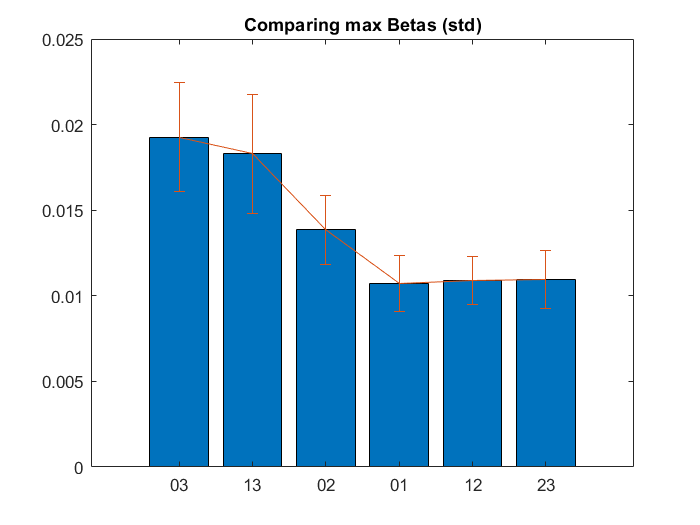


if doubleBattery == false
    for i = 1:2 
        disp(['Max Betas ', sides{i}])
        compareBetaBarChart(startindex, leng, js, channelSides{i});
        figure; 
    end
else 
    compareBetaBarChart(startindex, leng, js, channels);
end

Part 4: Show table of data across each run 

if doubleBattery == false
    for i = 1:2 
        disp(['Table of means and stds per channel ', sides{i}])
        maxMeanBetaAllRuns(startindex, js, leng, channelSides{i});
        figure; 
    end
else 
    maxMeanBetaAllRuns(startindex, js, leng, channels);
    figure; 
end

ans = 6×7 table
              Var1                Mean R1      Mean R2      Mean R3      STD R1       STD R2       STD R3  
    _________________________    _________    _________    _________    _________    _________    _________

    {'ZERO_THREE_RIGHT_3'   }     0.010851    0.0086132    0.0088128    0.0056191    0.0042252    0.0044667
    {'ONE_THREE_RIGHT_4'    }     0.008862    0.0083093    0.0088765    0.0052928    0.0046779    0.0047676
    {'ZERO_TWO_RIGHT_5'     }    0.0069586    0.0065528    0.0064597    0.0037535    0.0028878    0.0026932
    {'ZERO_AND_ONE_RIGHT_3' }    0.0050669    0.0052099    0.0048579    0.0022541    0.0029073    0.0023169
    {'ONE_AND_TWO_RIGHT_4'  }    0.0043877    0.0041024    0.0046128    0.0022148    0.0020691   

Part 5: Show all frequency data for contact pair that provides highest beta 

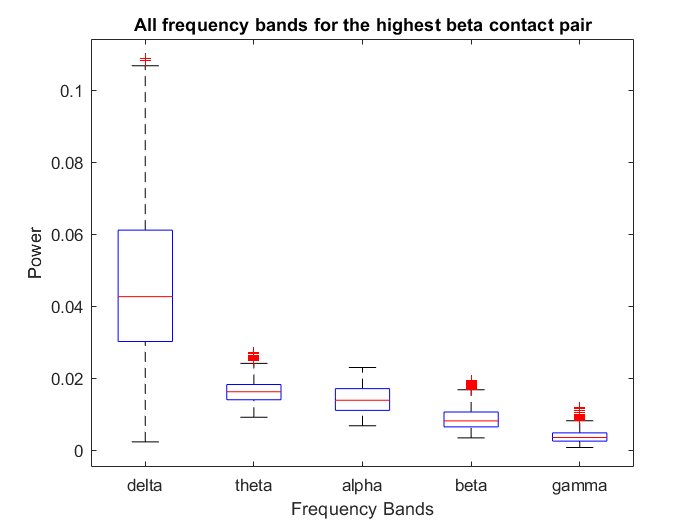

figure;
if doubleBattery == false
    for i = 1:2 
        disp(['All frequency data for ', legendChan{I}, sides{i}])
        allFreqBarChart(startindex, leng, js, highestBetas{i});
        figure; 
    end
else 
    allFreqBarChart(startindex, leng, js, highestBeta);
    figure; 
end

Part 6: Show variability between trials for each pair 

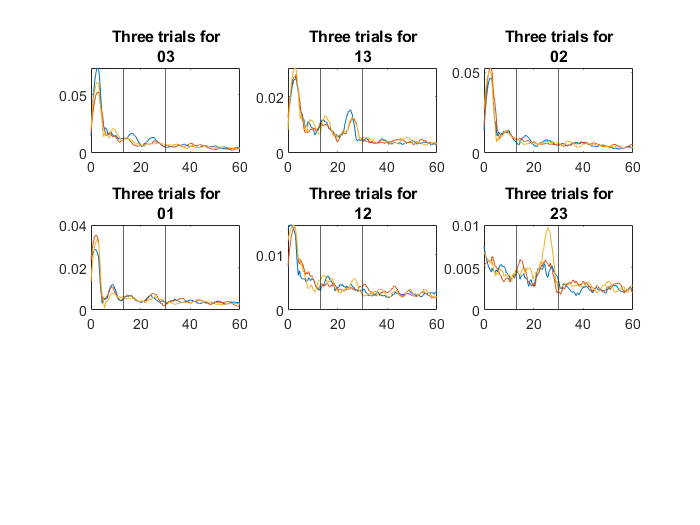

%graphEachTrials(startindex, js, leng, channels);
figure;
if doubleBattery == false
    for i = 1:2 
        disp(['Trial variability for the ', sides{i}])
        graphEachTrials(startindex, js, leng, channelSides{i});
        figure; 
    end
else 
   graphEachTrials(startindex, js, leng, channels);
   figure; 
end